## **3.1 Part A:**

%Loading an audio file
[y, Fs] = audioread("human_voice.wav"); % Read the audio file and store the signal in 'y' and sampling rate in 'Fs' 
t = linspace(0, length(y)/Fs, length(y)); % Generate a time vector corresponding to the the sampling rate of the signal
plot(t, y) % Plot the waveform in the time domain

1.)

The frequency of human_voice.wav is 48,000

3.) and 6.)

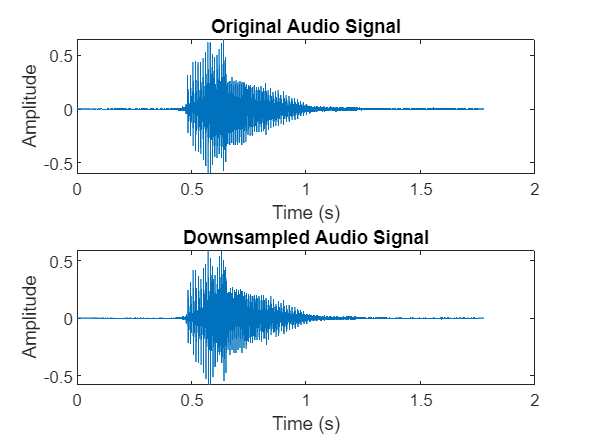

% Step 1: Read the audio file
[audio_data, original_Fs] = audioread('human_voice.wav');  % Replace with your file
% For mono audio, audio_data will be a column vector, and for stereo, it will be a 2-column matrix

% Step 2: Low-pass filter design
desired_Fs = 8000;  % Target downsampling frequency (8 kHz)
downsample_factor = original_Fs / desired_Fs;  % Calculate the downsampling factor

% Set the cutoff frequency of the low-pass filter (Nyquist limit of the new sampling rate)
cutoff_freq = desired_Fs / 2;  % Half of the desired sampling frequency
filter_order = 100;  % Filter order (higher values result in a sharper filter)

% Normalize the cutoff frequency
normalized_cutoff = cutoff_freq / (original_Fs / 2);  % Normalized cutoff (0 to 1)

% Design the low-pass FIR filter using the window method
b = fir1(filter_order, normalized_cutoff, 'low');  % FIR filter coefficients

% Step 3: Apply the low-pass filter to the audio signal
filtered_audio = filter(b, 1, audio_data);  % Apply the filter to each channel of the audio data

% Step 4: Subsample the signal (downsample)
downsampled_audio = filtered_audio(1:downsample_factor:end, :);  % Select every nth sample

% Step 5: Write the downsampled audio to a new file
audiowrite('downsampled_audio.wav', downsampled_audio, desired_Fs);  % Save as 8 kHz

% Plot the original and downsampled signals for comparison (optional)
subplot(2, 1, 1);
plot((1:length(audio_data)) / original_Fs, audio_data);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot((1:length(downsampled_audio)) / desired_Fs, downsampled_audio);
title('Downsampled Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

sound(downsampled_audio)

sound(y, Fs)

5.)


% Assuming you already have the following variables:
% original_Fs (original sampling frequency)
% desired_Fs (desired downsampled sampling frequency)
% audio_data (original audio data)

% Number of samples in the original audio
original_num_samples = length(audio_data);

% Time duration of the audio in seconds (total duration)
audio_duration = original_num_samples / original_Fs;

% Number of samples after downsampling
new_num_samples = desired_Fs * audio_duration;
original_num_samples = length(audio_data);
disp(['Number of samples in the original audio: ', num2str(original_num_samples)]);

Number of samples in the original audio: 85248


disp(['Number of samples after downsampling: ', num2str(new_num_samples)]);

Number of samples after downsampling: 14208


Number of samples after downsampling: 14,    208

7.) With the plots below at the same period, the downsampled audio signal is sampled less frequently, resulting in a more smooth and more rigid signal. The original audio signal used more samples, resulting in more variation.